# Augmented Tracking with Package: 

This live script tests the representative tracking scenario with a package and the adaptive controller developed in task 3. First, it will simulate the system response with a package and with the baseline controller, then it will study the system response with the package and the adaptive controller augmenting the baseline position controller. 

addpath("Models and Auxiliary Functions\")

## Baseline Model Initialization:

Parameters for the baseline model are taken straight from task 2. 

%Specify gravitational acceleration: 
g=9.81; %[m/s^2]

%Geometric and Inertial Properties:
UAV.Nr = 6; %number of rotors
UAV.m = 1.2; %[kg] UAV mass
UAV.J = diag([0.01 0.01 0.018]); % [kg m^2] inertia matrix
UAV.r_bg = [0 0 0]'; %[m] center of mass location in the body frame -> note I change it to a column vector. 
UAV.S = UAV.m*cross_matrix(UAV.r_bg); % [kg m] static moment

% Linear Aerodynamics
UAV.D_tauomega = diag([0.48 0.48 2.37]); %  angular velocity damping 
UAV.D_fv =  diag([0.055 0.055 0.022]); % linear velocity damping
UAV.D = [UAV.D_fv zeros(3,3); zeros(3,3) UAV.D_tauomega]; %-> there is a typo in the position of D_fv and D_tauomega on the data provided by the professor

% Propellers 
UAV.b = 0.215; %[m] arm length (ell in the slides)

k_f = 3.65e-6;                % [N/rad^2/s^2] Thrust characteristic coeff
sigma = 0.09;                 % [m] Torque-to-thrust ratio

%Construct input map:
%Rotors 1,3,5 rotate in the positive direction, 2,4,6 rotate in the
%negative direction
xiv=zeros(UAV.Nr,1);
xiv(1:2:UAV.Nr)=1; 
xiv(2:2:UAV.Nr)=-1;

gamma_r=2*pi/UAV.Nr*(0:UAV.Nr-1);
nr=[0;0;1];

F=nan(6,UAV.Nr);
for i=1:UAV.Nr
    pr=UAV.b*[cos(gamma_r(i));sin(gamma_r(i));0];
    pr_x=cross_matrix(pr);
    F(1:3,i)=nr;
    F(4:6,i)=(pr_x-xiv(i)*sigma*eye(3,3))*nr;
end

UAV.F=F;

%Actuator Dynamics: 
UAV.Omega_max = 10300; %[rpm] max spinning rate
UAV.Omega_min = 1260; %[rpm] min spinning rate
UAV.k_m = 1/0.05; % [s-1] Inverse of the time constant of the propeller motors

T_max=k_f*(UAV.Omega_max*2*pi/60)^2; %Unit conversion needed since kf is in N/(rad^2/s^2) and Omega_max and _min are given in rpm.
T_min=k_f*(UAV.Omega_min*2*pi/60)^2;

%For control allocation: (validated expression for F2 Plus)
F_2=F(3:6,:);
UAV.F_2_Plus=F_2'/(F_2*F_2');

%Define position controller: 
%Performance Goals: 
omega_n_p=1.75; %[rad/s]
zeta_p=0.8;    %[-]

%Convert to tuning: 
kp=omega_n_p^2;
kv=2*zeta_p*omega_n_p;

K_p=kp*eye(3,3);
K_v=kv*eye(3,3);

%Define attitude controller: 
%Tune controller: 
omega_n_a=20; %[rad/s]
zeta_a=1;     %[-]

%Tune k_r
k_r_hat=omega_n_a^2*diag(UAV.J);
A=[0,1,1;1,0,1;1,1,0];
k_r=A\k_r_hat;

%Tune K_omega:
K_omega=2*zeta_a*omega_n_a*UAV.J;

Initialize the trajectory at trim conditions (without the package) as well: 

%Initialize system: consider it starting from a trim condition at [0;0;1]
%Initialize postion and kinematics: 
p_b_i_0=[0;0;1];
q_0=[1;0;0;0];
v_b_0=[0;0;0];
omega_b_0=[0;0;0];
nu_b_0=[v_b_0;omega_b_0];

%Initialize rotor angular velocities: trim without the package!
T_0=UAV.m*g/UAV.Nr; 
Omega_r_0=sqrt(T_0/k_f)*ones(UAV.Nr,1);

Modification due to package: 

%Define package position and inertial parameters:
UAV.m_p=0.4; %[kg]
UAV.J_p=diag([0.01,0.01,0.01]); %[kg*m^2]
UAV.r_c=[0;0;-0.3]; %[m] distance between UAV's CoG and package's CoG -> 30 cm
UAV.m_t=UAV.m+UAV.m_p;
UAV.S_t=UAV.S+UAV.m_p*cross_matrix(UAV.r_c); %[kg*m]
UAV.J_t=UAV.J+UAV.J_p+UAV.m_p*(UAV.r_c'*UAV.r_c*eye(3,3)-UAV.r_c*UAV.r_c'); %[kg*m^2]

UAV.MM=[UAV.m_t*eye(3,3),UAV.S_t';UAV.S_t,UAV.J_t];
UAV.MM_inv=inv(UAV.MM);

Control effectiveness and trajectory parameters: 

%Simulate system response: 
Lambda=eye(6,6);
R_turn_H=5;
R_turn_V=1.5;

## Package Delivery (0.4kg) with Baseline Controller: 

Qualitative Assessment

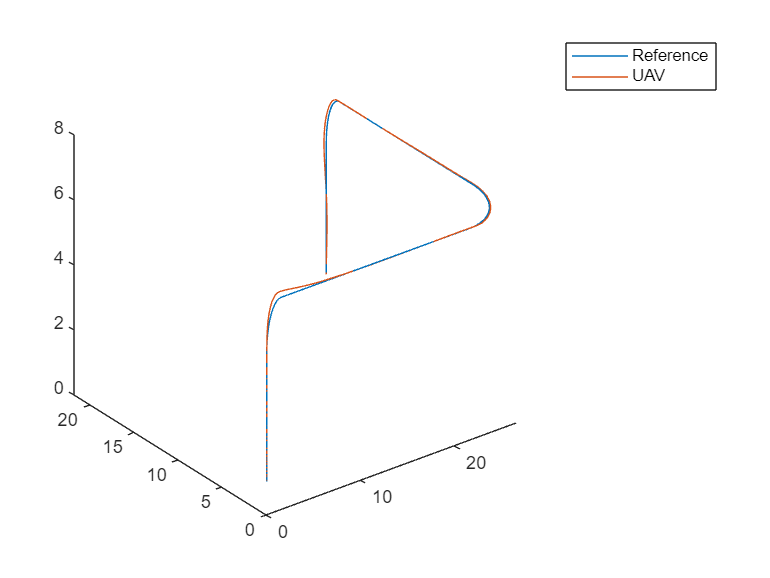

simout=sim("Package_Baseline_Trajectory_Model.slx","StopTime","25","RelTol","1e-6");
%Plot system response against reference trajectory: 
%System trajectory:
model_trajectory=nan(3,length(simout.p_b_i.time));

for i=1:length(simout.p_b_i.time)
    model_trajectory(:,i)=simout.p_b_i.data(:,1,i);
end

%Plot trajectory:
tv=linspace(0,25,1000);
ref_trajectory=nan(3,length(tv));

for i=1:length(tv)
    [ref_trajectory(:,i),~,~,~]=representative_trajectory(tv(i),R_turn_V,R_turn_H);
end

figure
clf
plot3(ref_trajectory(1,:),ref_trajectory(2,:),ref_trajectory(3,:),'DisplayName','Reference')
hold on
plot3(model_trajectory(1,:),model_trajectory(2,:),model_trajectory(3,:),'DisplayName','UAV')
legend()

Quantitative assessment: 

T=25; %simulation duration. 

%Evaluate reference trajectory at adequate timesteps:
model_velocity=nan(3,length(simout.v_i.time));
ref_position=nan(3,length(simout.p_b_i.time));
ref_velocity=nan(3,length(simout.v_i.time));

pos_integrand=nan(1,length(simout.p_b_i.time));
vel_integrand=nan(1,length(simout.v_i.time));

for i=1:length(simout.p_b_i.time)
    [ref_position(:,i),~,~,~]=representative_trajectory(simout.p_b_i.time(i),R_turn_V,R_turn_H);
    pos_integrand(i)=(model_trajectory(:,i)-ref_position(:,i))'*(model_trajectory(:,i)-ref_position(:,i));
end

for i=1:length(simout.v_i.time)
    [~,ref_velocity(:,i),~,~]=representative_trajectory(simout.v_i.time(i),R_turn_V,R_turn_H);
    model_velocity(:,i)=simout.v_i.data(:,1,i);
    vel_integrand(i)=(model_velocity(:,i)-ref_velocity(:,i))'*(model_velocity(:,i)-ref_velocity(:,i));
end


pos_Error=sqrt(1/T*(trapz(simout.p_b_i.time',pos_integrand)));
vel_Error=sqrt(1/T*(trapz(simout.p_b_i.time',vel_integrand)));

display(pos_Error)

pos_Error = 0.1465

display(vel_Error)

vel_Error = 0.1727

## Robust PO-PBMRAC with smart integrator: 

This is the culmination of the adaptive scheme. It combines a robust implementation of PBMRAC which relies on the projection operator with a smart integrator to avoid numerical issues with a singular Lambda matrix.  

%For predictor dynamics: 
A_p=[zeros(3,3),eye(3,3);zeros(3,3),zeros(3,3)];
B_p=[zeros(3,3);eye(3,3)];
B_pT=B_p';

%Initialize adaptive laws: 
lambda_hat_0=[1;1;1];
a_e_tilde_hat_0=[0;0;0];


%Initialize predictor: 
p_i_hat_0=p_b_i_0;
v_i_hat_0=[0;0;0];
x_hat_0=[p_i_hat_0;v_i_hat_0];

%Tune adaptive controller: 
L=100*eye(6,6);
Gamma_a=10*eye(6,6);

%Define minimum lambda for smart integrator: 
lambda_min=0.1; 
%Define variables needed for projection operator: 
epsilon=0.1; %leaves 95% of the range unaffected
lambda_max=2;
a_e_tilde_max=UAV.m*g;

Now let's test performance in the representative trajectory: 

Qualitative Assessment

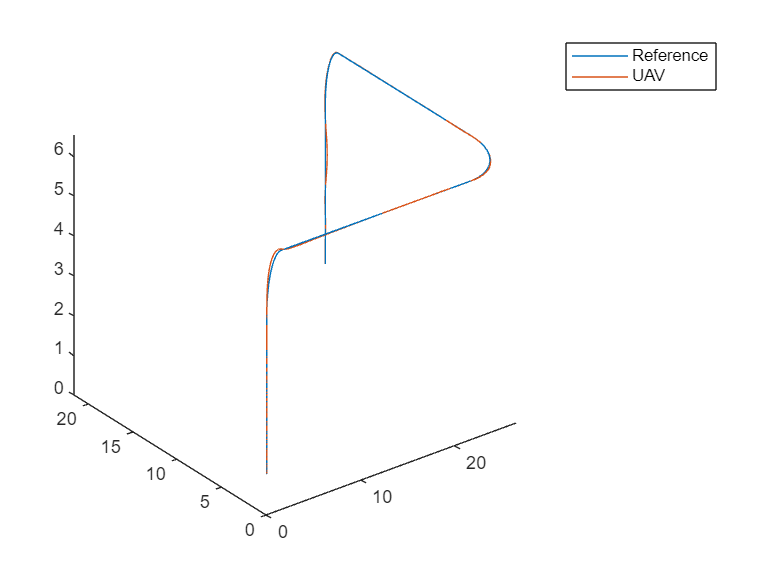

simout=sim("Augmented_Package_Trajectory_Model.slx","StopTime","25","RelTol","1e-6");
%Plot system response against reference trajectory: 
%System trajectory:
model_trajectory=nan(3,length(simout.p_b_i.time));

for i=1:length(simout.p_b_i.time)
    model_trajectory(:,i)=simout.p_b_i.data(:,1,i);
end

%Plot trajectory:
tv=linspace(0,25,1000);
ref_trajectory=nan(3,length(tv));

for i=1:length(tv)
    [ref_trajectory(:,i),~,~,~]=representative_trajectory(tv(i),R_turn_V,R_turn_H);
end

figure
clf
plot3(ref_trajectory(1,:),ref_trajectory(2,:),ref_trajectory(3,:),'DisplayName','Reference')
hold on
plot3(model_trajectory(1,:),model_trajectory(2,:),model_trajectory(3,:),'DisplayName','UAV')
legend()

Quantitative assessment: 

T=25; %simulation duration. 

%Evaluate reference trajectory at adequate timesteps:
model_velocity=nan(3,length(simout.v_i.time));
ref_position=nan(3,length(simout.p_b_i.time));
ref_velocity=nan(3,length(simout.v_i.time));

pos_integrand=nan(1,length(simout.p_b_i.time));
vel_integrand=nan(1,length(simout.v_i.time));

for i=1:length(simout.p_b_i.time)
    [ref_position(:,i),~,~,~]=representative_trajectory(simout.p_b_i.time(i),R_turn_V,R_turn_H);
    pos_integrand(i)=(model_trajectory(:,i)-ref_position(:,i))'*(model_trajectory(:,i)-ref_position(:,i));
end

for i=1:length(simout.v_i.time)
    [~,ref_velocity(:,i),~,~]=representative_trajectory(simout.v_i.time(i),R_turn_V,R_turn_H);
    model_velocity(:,i)=simout.v_i.data(:,1,i);
    vel_integrand(i)=(model_velocity(:,i)-ref_velocity(:,i))'*(model_velocity(:,i)-ref_velocity(:,i));
end


pos_Error=sqrt(1/T*(trapz(simout.p_b_i.time',pos_integrand)));
vel_Error=sqrt(1/T*(trapz(simout.p_b_i.time',vel_integrand)));

display(pos_Error)

pos_Error = 0.0685

display(vel_Error)

vel_Error = 0.1540